**Half-wave Rectifier as a Battery Charger**

V_B - Battery voltage in volts

t - Time interval for the p

w=2*pi*f - angular velocity

R = 100

R = 100

f = 50

f = 50

v_gamma = 0.6

v_gamma = 0.6000

V_B = 12

V_B = 12

w=2*pi*f

w = 314.1593

t=linspace(0,0.02,360)

t =          0    0.0001    0.0001    0.0002    0.0002    0.0003    0.0003    0.0004    0.0004    0.0005    0.0006    0.0006    0.0007    0.0007    0.0008    0.0008    0.0009    0.0009    0.0010    0.0011    0.0011    0.0012    0.0012    0.0013    0.0013    0.0014    0.0014    0.0015    0.0016    0.0016    0.0017    0.0017    0.0018    0.0018    0.0019    0.0019    0.0020    0.0021    0.0021    0.0022    0.0022    0.0023    0.0023    0.0024    0.0025    0.0025    0.0026    0.0026    0.0027    0.0027


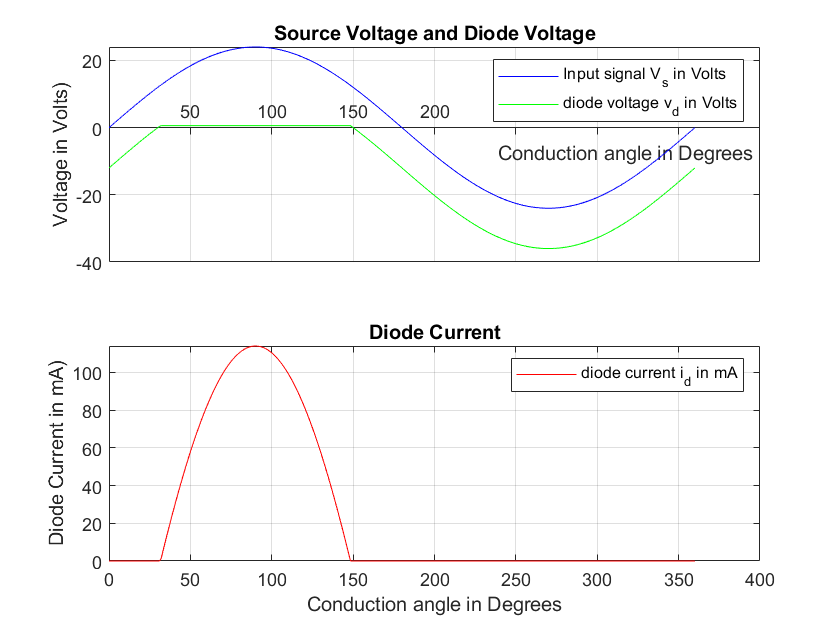

theta=rad2deg(t*w); %the angle theta
v_s=24.*sind(theta); %the input signal;
for n=1:360
 if (v_s(n)>=v_gamma + V_B) %forward bias condition
 i_diode(n)=(v_s(n)-(v_gamma+V_B)).*1000/R;%diode current in mA 
%when conduction 
 v_diode(n)=v_gamma; %diode voltage when conducting is simply 
%the cut-in voltage
 else %reverse bias condition
 v_diode(n)=v_s(n)-V_B; % is the sum of the battery voltage and 
%source voltage-the polarity
 %of the source changes making the two
%voltages additive in the negative
%direction 
 i_diode(n)=0;
 end
end
figure %plotting the graphs
subplot(2,1,1)
plot(theta,v_s,'b',theta,v_diode,'g');
grid on
set(gca,'XAxisLocation','origin','YAxisLocation','origin')
title('Source Voltage and Diode Voltage');
xlabel('Conduction angle in Degrees');
ylabel('Voltage in Volts)');
legend('Input signal V_s in Volts','diode voltage v_d in Volts');
subplot(2,1,2)
plot(theta,i_diode,'r');
title('Diode Current');
xlabel('Conduction angle in Degrees');
ylabel('Diode Current in mA)');
legend('diode current i_d in mA');
grid on